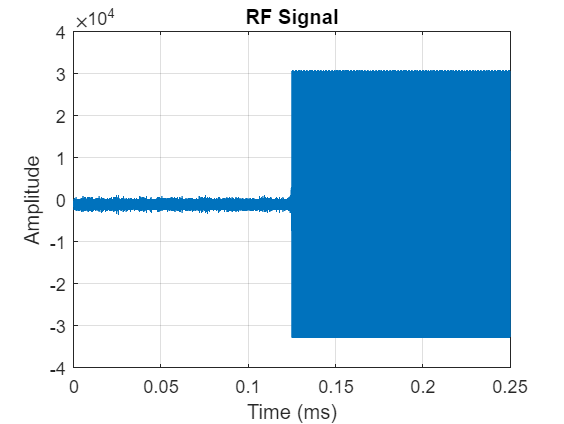

data = load('BEEBEERUN_0000100002.mat');  % Replace 'filename.mat' with your actual file name

% Access your signal. Replace 'data' and 'signal' if your variable or field has a different name.
rf_signal = Channel_1.Data;  

% Create a time vector based on the sample rate
fs = 20e9;  % sample rate of 20 GHz
t = (0:length(rf_signal)-1)/fs;  % time vector in seconds

% Plot the signal
figure;  % Create a new figure
plot(t*1e3, rf_signal);  % Convert time to ms for the plot
xlabel('Time (ms)');
ylabel('Amplitude');
title('RF Signal');
grid on;